# Transform Testing

R = imread('raw/20250321T192420_651_StackInput.tiff');
I = imread('raw/20250321T193020_675_StackInput.tiff');
dark = imread('darkframe.tiff');

Get points

r_points = get_star_tracking_points(R-dark, .2)

r_points =            2         899
          55         665
          58         842
          66          61
          81        1060
         133         396
         145         259
         160        1264
         178        1398
         190        1378
         230         139
         253        1119
         306         998
         322        1322
         326         594


i_points = get_star_tracking_points(I-dark, .2)

i_points =            2         899
          55         665
          58         842
          66          61
          81        1060
         133         396
         145         259
         160        1264
         178        1398
         230         139
         253        1119
         306         998
         322        1322
         326         594
         329         593


Nearest Neighbour Matching

[r_points,i_points] = match_points(r_points,i_points);

Transform

tform = estimateGeometricTransform2D(i_points, r_points,'similarity');

Warp

outputView = imref2d(size(R));
aligned = imwarp(I, tform, 'OutputView', outputView);

Alignment

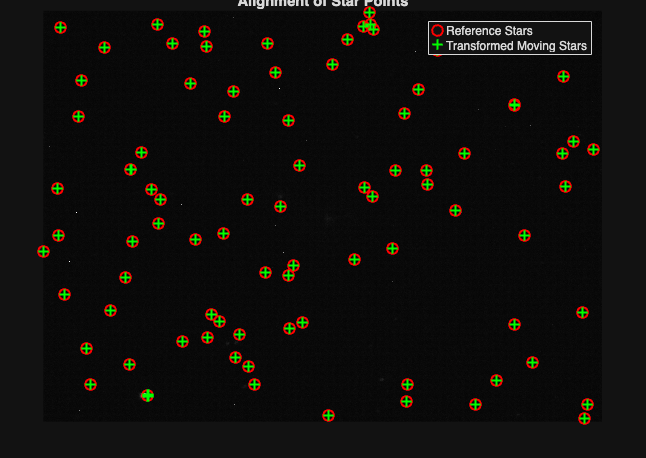

% apply transformation to moving points
movingPointsTransformed = transformPointsForward(tform, i_points);

% visualize
figure; imshow(R, []); hold on;
plot(r_points(:,1), r_points(:,2), 'ro', 'MarkerSize', 8, 'LineWidth', 1.5);
plot(movingPointsTransformed(:,1), movingPointsTransformed(:,2), 'g+', 'MarkerSize', 8, 'LineWidth', 1.5);
legend('Reference Stars', 'Transformed Moving Stars');
title('Alignment of Star Points');